clc;
clear;
close all;

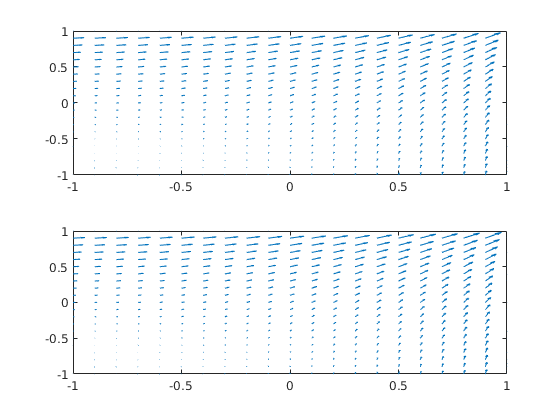

step = 1e-1;
x = -1:step:1;
y = -1:step:1;
[xx, yy] = meshgrid(x,y);
nx = numel(x);
ny = numel(y);
f = zeros(nx,ny);
g = zeros(nx,ny,2);
H = zeros(nx,ny,2,2);
for i=1:nx
    for j=1:ny
        [f(i,j),g(i,j,:),H(i,j,:,:)] = objectiveFunction([x(i);y(j)]);
    end
end

% gradient
[gy, gx] = gradient(f,step);

% plot gradient
figure;
subplot(211); quiver(xx,yy,g(:,:,1),g(:,:,2));
xlim([-1,1]); ylim([-1,1]);
subplot(212); quiver(xx,yy,gx,gy);
xlim([-1,1]); ylim([-1,1]);

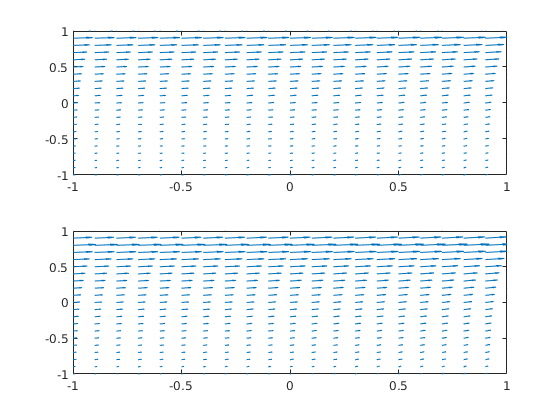

% hessian
[gyy,gyx] = gradient(gy,step);
[gxy,gxx] = gradient(gx,step);

% plot top row hessian
figure;
subplot(211); quiver(xx,yy,H(:,:,1,1),H(:,:,1,2));
xlim([-1,1]); ylim([-1,1]);
subplot(212); quiver(xx,yy,gxx,gxy);
xlim([-1,1]); ylim([-1,1]);

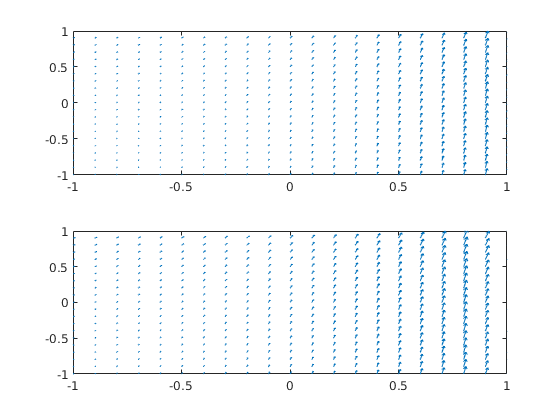

% plot bottom row hessian
figure;
subplot(211); quiver(xx,yy,H(:,:,2,1),H(:,:,2,2));
xlim([-1,1]); ylim([-1,1]);
subplot(212); quiver(xx,yy,gyx,gyy);
xlim([-1,1]); ylim([-1,1]);